syms x y
z_total = 0;
a_divot = -2;
a_barrel = 30;
a_wall = -10;
numPoints = 30;

% top right obstacle
z_total = makeDivot([-0.25 -1], z_total, a_divot);


% bottom right obstacle
z_total = makeDivot([1 -0.7], z_total, a_divot);


% bottom left obstacle
z_total = makeDivot([1.41 -2], z_total, a_divot);


% BoB
z_total = makeDivot([0.75 -2.5], z_total, a_barrel);

% top right corner
z_total = makeDivot([-1.5 1], z_total, a_wall);

% bottom right wall
z_total = makeDivot([2.5 1], z_total, a_wall);

% top left wall
z_total = makeDivot([-1.5 -3.37], z_total, a_wall);

% bottom left wall
z_total = makeDivot([2.5 -3.37], z_total, a_wall);

% % top wall
% % bottom left to top left
% startPoint = [-1.5 -3.37]; % left
% endPoint = [-1.5 1]; % right
% z_total = makeLineOfDivots(startPoint,endPoint,numPoints,z_total,a_divot);
% 
% 
% %right wall
% % top right to bottom right
% startPoint = [-1.5 1]; % top
% endPoint = [2.5 1]; % bottom
% z_total = makeLineOfDivots(startPoint,endPoint,numPoints,z_total,a_divot);
% 
% %bottom wall
% % bottom right to bottom left
% startPoint = [2.5 1]; % right
% endPoint = [2.5 -3.37]; % left
% z_total = makeLineOfDivots(startPoint,endPoint,numPoints,z_total,a_divot);
% 
% 
% %left wall
% % bottom left to top left
% startPoint = [2.5 -3.37]; % bottom
% endPoint = [-1.5 -3.37]; % top
% z_total = makeLineOfDivots(startPoint,endPoint,numPoints,z_total,a_divot);

clf
[X,Y] = meshgrid(linspace(-1.5,2.5,50),linspace(-3.37,1,50));
Z = double(subs(z_total,{x,y},{X,Y}));

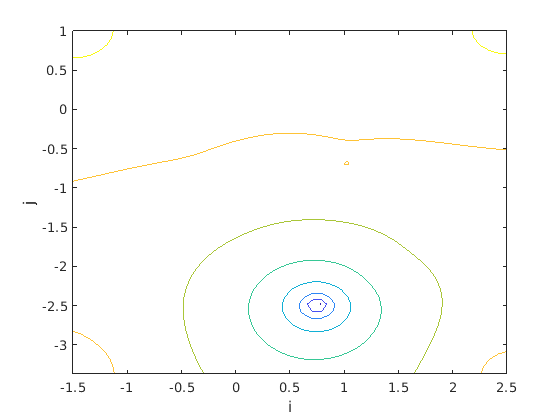

contour(X,Y,Z)
xlabel('i')
ylabel('j')
zlabel('k')

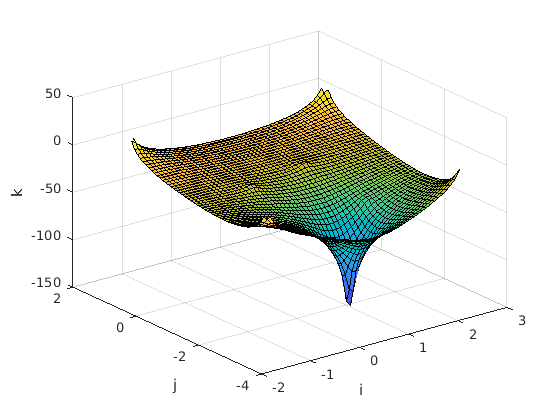

surf(X,Y,Z)
xlabel('i')
ylabel('j')
zlabel('k')

% gradient descent
flatland_assignment(z_total)

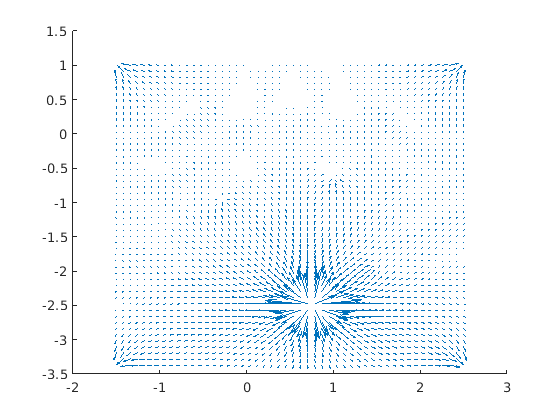

% gradient vector plot
[px, py] = gradient(Z);
figure
% contour(X, Y, Z)
hold on
quiver(X, Y, px, py, 4)
hold off